    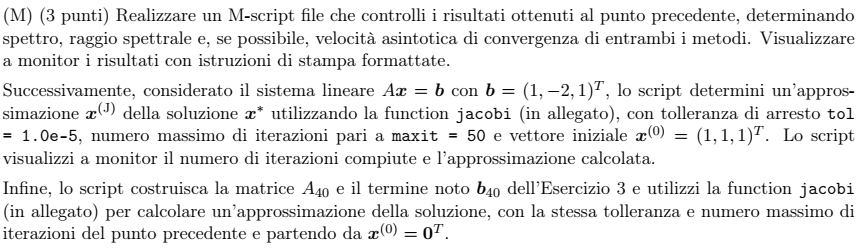

M=[...
    4 -1 1;...
    4 -8 1;...
    -2 1 5;...
    ];

J = eye(3,3);
GS = J;

J = ( sym( diag(1./diag(M)))*(-tril(M,-1)-triu(M,1) ) )

$$J = \left(\begin{array}{ccc} 0 & \frac{1}{4} & -\frac{1}{4}\\ \frac{1}{2} & 0 & \frac{1}{8}\\ \frac{2}{5} & -\frac{1}{5} & 0 \end{array}\right)$$

spettroJ = eig( J )

$$spettroJ = \left(\begin{array}{c} \frac{3^{1/3}\,10^{2/3}}{20}\\ \frac{3^{1/3}\,10^{2/3}\,\left(-\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2}\right)}{20}\\ -\frac{3^{1/3}\,10^{2/3}\,\left(\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2}\right)}{20} \end{array}\right)$$

rhoJ = max( abs( spettroJ ) );
velJ = -log( rhoJ );

GS = sym( -tril(M)\triu(M,1) )

$$GS = \left(\begin{array}{ccc} 0 & \frac{1}{4} & -\frac{1}{4}\\ 0 & \frac{1}{8} & 0\\ 0 & \frac{3}{40} & -\frac{1}{10} \end{array}\right)$$

spettroGS = eig (GS)

$$spettroGS = \left(\begin{array}{c} -\frac{1}{10}\\ 0\\ \frac{1}{8} \end{array}\right)$$

rhoGS = max( abs( spettroGS ) );
velGS = -log( rhoGS );

fprintf("La velocità di convergenza della matrice di Jacobi è: %g", velJ);

La velocità di convergenza della matrice di Jacobi è: 1.09447

fprintf("La velocità di convergenza della matrice di Gauss-Seidel è: %g", velGS);

La velocità di convergenza della matrice di Gauss-Seidel è: 2.07944


b=zeros(3,1);
b=[1;-2;1];

tol = 1.0e-5;
maxit = 50;
xJ = ones(3,1);
%xJ = zeros(3,1);%Non strettamente necessario perchè xJ è piccolo
[xJ, it]= jacobi(M, b, xJ, maxit , tol);

Sarebbe meglio fare tutto in una sola riga senza salvare tutto. Meno memoria usata


fprintf("\nApprossimazione di x ottenuta in %g passi e il vettore risultante è:\n",it);


Approssimazione di x ottenuta in 13 passi e il vettore risultante è:


disp(xJ);

    0.2987
    0.4286
    0.2338



Gauss-Seidel: (D-L)^(-1)* U

Parte 2

d=4*ones(40,1);
d0=ones(40,1);
d0(2:2:40) = -d0(2:2:40);
An=sym(spdiags([d0 d d0], -1:1, 40, 40));

b=sym(-d0);
xJ=zeros(40,1);
[xJ,it]=jacobi(an,b,xJ,maxit,tol);

fprintf("\nApprossimazione di x ottenuta in %g passi e il vettore risultante è:\n",it);


Approssimazione di x ottenuta in 18 passi e il vettore risultante è:


disp(xJ);

$$\left(\begin{array}{c} -\frac{5869346601}{34359738368}\\ \frac{5441188137}{17179869184}\\ -\frac{1650186969}{17179869184}\\ \frac{5137967205}{17179869184}\\ -\frac{1721770677}{17179869184}\\ \frac{5154869217}{17179869184}\\ -\frac{429445605}{4294967296}\\ \frac{5153929515}{17179869184}\\ -\frac{859002543}{8589934592}\\ \frac{5153982837}{17179869184}\\ -\frac{1717992801}{17179869184}\\ \frac{5153980185}{17179869184}\\ -\frac{1717993509}{17179869184}\\ \frac{5153980413}{17179869184}\\ -\frac{6871973883}{68719476736}\\ \frac{10307960829}{34359738368}\\ -\frac{6871973889}{68719476736}\\ \frac{157287}{524288}\\ -\frac{52429}{524288}\\ \frac{157287}{524288}\\ -\frac{52429}{524288}\\ \frac{157287}{524288}\\ -\frac{52429}{524288}\\ \frac{20615921663}{68719476736}\\ -\frac{3435986943}{34359738368}\\ \frac{20615921653}{68719476736}\\ -\frac{1717993471}{17179869184}\\ \frac{5153980375}{17179869184}\\ -\frac{1717993395}{17179869184}\\ \frac{5153980475}{17179869184}\\ -\frac{1717994279}{17179869184}\\ \frac{2576987935}{8589934592}\\ -\frac{1717976505}{17179869184}\\ \frac{644256083}{2147483648}\\ -\frac{1718289739}{17179869184}\\ \frac{5152716151}{17179869184}\\ -\frac{1712655735}{17179869184}\\ \frac{5176572083}{17179869184}\\ -\frac{1813729379}{17179869184}\\ \frac{9496805359}{34359738368} \end{array}\right)$$